# Integrator Lab: Solving First Order ODEs in MATLAB and Picard Approximation

This lab will teach you to numerically solve first order ODEs using a built in MATLAB integrator, `ode45`.  `ode45` is a good, general purpose tool for integrating first order equations (and first order systems). It is not always the right algorithm, but it is usually the right algorithm to try first. This lab will also teach you how to manipulate symbolic functions in MATLAB.

You will learn how to use the `ode45` routine, how to interpolate between points, and how MATLAB handles data structures. You will also learn how to use MATLAB for exact symbolic calculations and write your own Picard approximation code.

Opening the m-file lab2.m in the MATLAB editor, step through each part using cell mode to see the results. Compare the output with the PDF, which was generated from this m-file.

There are eight exercises in this lab that are to be handed in at the end of the lab. Write your solutions in the template, including appropriate descriptions in each step. Save the .m file and submit it online using Quercus.

## Student Information

Student Name: Jaehah Shin

Student Number: 1008851137

## Set up an inline function representation of an ODE and solve it

MATLAB has many built in routines for solving differential equations of the form

`y' = f(t,y)`

We will solve them using `ode45`, a high precision integrator. To do this, we will need to construct an inline function representation of `f`, an initial condition, and specify how far we want MATLAB to integrate the problem. Once we have set these, we pass the information to `ode45` to get the solution.

For a first example, we will solve the initial value problem

`y' = y, y(0) = 1`

which has as its answer `y = e^t`.

% Set up the right hand side of the ODE as an inline function
f = @(t,y) y;

% The initial conditions
t0 = 0;
y0 = 1;

% The time we will integrate until
t1 = 2;

soln = ode45(f, [t0, t1], y0);

## Examining the output

When we execute the `ode45`, it returns a data structure, stored in soln. We can see the pieces of the data structure with a display command:

disp(soln);

     solver: 'ode45'
    extdata: [1×1 struct]
          x: [0 0.2000 0.4000 0.6000 0.8000 1 1.2000 1.4000 1.6000 1.8000 2]
          y: [1 1.2214 1.4918 1.8221 2.2255 2.7183 3.3201 4.0552 4.9530 6.0496 7.3891]
      stats: [1×1 struct]
      idata: [1×1 struct]



## Understanding the components of the solution data structure

The most important elements of the data structure are stored in the `x` and `y` components of the structure; these are vectors. Vectors `x` and `y` contain the points at which the numerical approximation to the initial vlaue problem has been computed. In other words, `y(j)` is the approximate value of the solution at `x(j)`.

**NOTE:** Even though we may be studying a problem like `u(t)` or `y(t)`, MATLAB will always use `x` for the independent variable and `y` for the dependent variable in the data structure.

Pieces of the data structure can be accessed using a period, as in C/C++ or Java. See the examples below:

% Display the values of |t| at which |y(t)| is approximated
fprintf(' Vector of t values: ');

 Vector of t values: 

disp(soln.x);

         0    0.2000    0.4000    0.6000    0.8000    1.0000    1.2000    1.4000    1.6000    1.8000    2.0000



% Display the the corresponding approximatations of |y(t)|
fprintf(' Vector of y values: ');

 Vector of y values: 

disp(soln.y);

    1.0000    1.2214    1.4918    1.8221    2.2255    2.7183    3.3201    4.0552    4.9530    6.0496    7.3891




% Display the approximation of the solution at the 3rd point:
fprintf(' Third element of the vector of t values: %g\n',soln.x(3));

 Third element of the vector of t values: 0.4


fprintf(' Third element of the vector of y values: %g\n',soln.y(3));

 Third element of the vector of y values: 1.49182


## Visualizing and comparing the solution

We can now visualize the solution at the computed data points and compare with the exact solution.

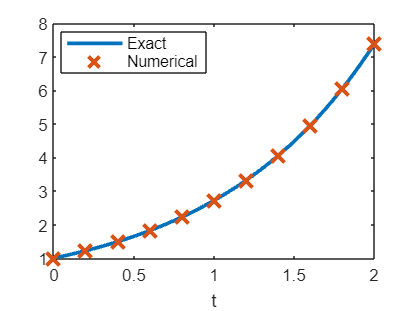

% Construct the exact solution
tt = linspace(0,2,50);
yy = exp(tt);

% Plot both on the same figure, plotting the approximation with x's
plot(tt, yy, soln.x, soln.y, 'x', 'MarkerSize',10, 'LineWidth', 2);
% NOTE: the MarkerSize and LineWidth are larger than their defaults of 6
% and 1, respectively.  This makes the print out more readable.

% Add a label to the axis and a legend
xlabel('t');
legend('Exact', 'Numerical','Location','Best');

## Exercise 1

Objective: Solve an initial value problem and plot both the numerical approximation and the corresponding exact solution.

Details: Solve the IVP

`y' = y tan t + sin t, y(0) = -1/2`

from `t = 0` to `t = pi`.

Compute the exact solution (by hand), and plot both on the same figure for comparison, as above.

% Set up the right hand side of the ODE as an inline function
f = @(t,y) y*tan(t) + sin(t);

% The initial conditions
t0 = 0;
y0 = -1/2;

% The time we will integrate until
t1 = pi;

sol_by_45 = ode45(f, [t0, t1], y0);
disp(sol_by_45);

     solver: 'ode45'
    extdata: [1×1 struct]
          x: [0 0.3142 0.6283 0.9425 1.2566 1.2881 1.3195 1.4765 1.5177 1.5588 1.6491 1.7455 2.0597 2.3739 2.6880 3.0022 3.1416]
          y: [-0.5000 -0.4755 -0.4045 -0.2939 -0.1545 -0.1395 -0.1243 -0.0471 -0.0266 -0.0060 0.0391 0.0869 0.2348 0.3597 0.4494 0.4951 0.5000]
      stats: [1×1 struct]
      idata: [1×1 struct]



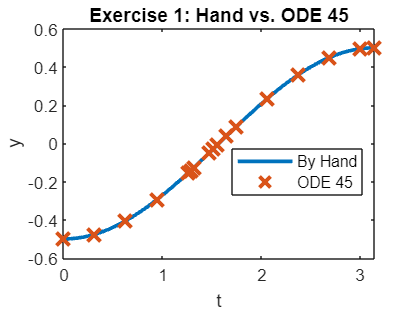

%      solver: 'ode45'
%    extdata: [1×1 struct]
%          x: [0 0.3142 0.6283 0.9425 1.2566 1.2881 1.3195 1.4765 1.5177 1.5588 1.6491 1.7455 2.0597 2.3739 2.6880 3.0022 3.1416]
%          y: [-0.5000 -0.4755 -0.4045 -0.2939 -0.1545 -0.1395 -0.1243 -0.0471 -0.0266 -0.0060 0.0391 0.0869 0.2348 0.3597 0.4494 0.4951 0.5000]
%      stats: [1×1 struct]
%      idata: [1×1 struct]

% Now solve by hand.

% use integartion factor to solve this. 
% This will lead to y = (sin^2t / 2cost) -0.5 /cost
% (y = sin^2(t)/2cost) + C/cost before putting intinal conditions)
% By solving constant with intial condition yields
% C = -0.5, which will lead to above equation.
tt = linspace(0, pi, 50);
yy = (sin(tt).^2)./(2*cos(tt)) - 0.5./(cos(tt));



% Plot both on the same figure, plotting the approximation with x's
plot(tt, yy, sol_by_45.x, sol_by_45.y, 'x', 'MarkerSize',10, 'LineWidth', 2);
% NOTE: the MarkerSize and LineWidth are larger than their defaults of 6
% and 1, respectively.  This makes the print out more readable.

% Add a label to the axis and a legend
xlabel('t');
ylabel("y");
legend('By Hand', 'ODE 45','Location','Best');
title("Exercise 1: Hand vs. ODE 45")

Your submission should show the construction of the inline function, the use of ode45 to obtain the solution, a construction of the exact solution, and a plot showing both. In the comments, include the exact solution.

Label your axes and include a legend.

## Computing an approximation at a specific point

As you should be able to see by examining `soln.x`, ode45 returns the solution at a number of points between `t0` and `t1`. But sometimes we want to know the solution at some intermediate point.

To obtain this value, we need to interpolate it in a consistent way. Fortunately, MATLAB provides a convenient function, `deval`, specifically for this.

% Compute the solution at t = .25:
deval(soln, .25)

ans = 1.2840


% Compute the solution at t = 1.6753:
fprintf(' Solution at 1.6753: %g\n', deval(soln, 1.6753));

 Solution at 1.6753: 5.3404



% Compute the solution at 10 grid points between .45 and 1.65:
tinterp = linspace(.45, 1.65, 10);
deval(soln, tinterp)

ans =     1.5683    1.7920    2.0476    2.3396    2.6734    3.0547    3.4903    3.9882    4.5570    5.2070



% Alternatively:
deval(soln, linspace(.45, 1.65, 10))

ans =     1.5683    1.7920    2.0476    2.3396    2.6734    3.0547    3.4903    3.9882    4.5570    5.2070


## Exercise 2

Objective: Interpolate a solution at a number of grid points

hi = deval(sol_by_45, linspace(2,3,10))

hi =     0.2081    0.2572    0.3032    0.3454    0.3833    0.4166    0.4447    0.4673    0.4841    0.4950


disp(hi);

    0.2081    0.2572    0.3032    0.3454    0.3833    0.4166    0.4447    0.4673    0.4841    0.4950




% double check where the bottom colum come from 

Details: For the solution you computed in exercise 1, use deval to compute the interpolated values at 10 grid points between 2 and 3.

## Errors, Step Sizes, and Tolerances

As you may have noticed, in contrast to the IODE software, at no point do we set a step size for our solution. Indeed, the step size is set adaptively to conform to a specified error tolerance.

Roughly speaking, given the solution at `(t_j, y_j)`, `ode45` computes two approximations of the solution at `t_{j+1} = t_j + h`; one is of greater accuracy than the other. If the difference is below a specified tolerance, the step is accepted and we continue. Otherwise the step is rejected and the smaller step size, `h`, is used; it is often halved.

We can compute the global truncation error at each solution point, figure out the maximum error, and visualize this error (on a linear-log scale):

% Compute the exact solution
yexact = exp(soln.x);

% Compute the pointwise error; note the use of MATLAB's vectorization
err = abs(yexact - soln.y);

disp(err);

   1.0e-06 *

         0    0.0152    0.0371    0.0679    0.1106    0.1688    0.2475    0.3526    0.4922    0.6764    0.9179




fprintf('maximum error: %g \n', max(err));

maximum error: 9.17923e-07 


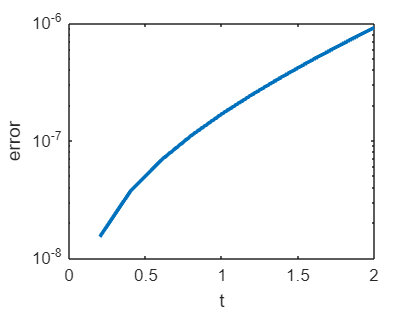


semilogy(soln.x, err, 'LineWidth', 2);
xlabel('t');
ylabel('error');

## Exercise 3

Objective: Examine the error of a solution generated by `ode45`

% computing the exact solutino:
yexact = (sin(sol_by_45.x).^2)./(2*cos(sol_by_45.x)) - 0.5./(cos(sol_by_45.x));

% Error?
ERROR = abs(yexact - sol_by_45.y);
disp(ERROR);

   1.0e-04 *

         0    0.0001    0.0006    0.0021    0.0070    0.0077    0.0087    0.0230    0.0408    0.1807    0.0254    0.0114    0.0068    0.0055    0.0047    0.0043    0.0043



fprintf("Maximum ERROR: %g \n", max(ERROR));

Maximum ERROR: 1.8068e-05 


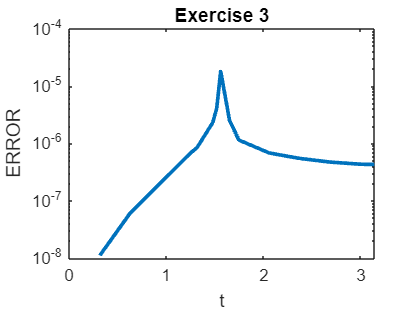

% Maximum ERROR: 1.8068e-05 

% Error is largest at that point near t = 1.5,
% the reason because it has the largest error is as at @ 1.5s is the rate of
% chage of the derivate is the higest. Smaller steps
% sizes are required to reduce the error. 
semilogy(sol_by_45.x, ERROR, "LineWidth", 2);
xlabel("t");
ylabel("ERROR");
title("Exercise 3")

Details: For your solution to exercise 1, compute the pointwise error, identify the maximum value of the error, and visualize the error on a linear-log plot (use semilogy to plot the log of the error vs. t). Write in the comments where the error is largest, and give a brief (1-2 sentences) explanation of why it is largest there. Make sure to label your axes.

## Exercise 4

Objective: Solve and visualize a nonlinear ode using ode45

Details: Solve the IVP

`y' = 1 / y^2 , y(1) = 1`

from `t=1` to `t=10` using `ode45`. Find the exact solution and compute the maximum pointwise error. 

Then plot the approximate solution and the exact solution on the same axes. --> I plotted

f = @(t,y) 1/(y^2)

f = function_handle with value:
    @(t,y)1/(y^2)


% The initial conditions
t0 = 1;
y0 = 1;
% The time we will integrate until
t1 = 10;
sol_45 = ode45(f, [t0, t1], y0);
disp(sol_45);

     solver: 'ode45'
    extdata: [1×1 struct]
          x: [1 1.2010 2.1010 3.0010 3.9010 4.8010 5.7010 6.6010 7.5010 8.4010 9.3010 10]
          y: [1 1.1703 1.6248 1.9119 2.1319 2.3139 2.4711 2.6105 2.7364 2.8516 2.9583 3.0361]
      stats: [1×1 struct]
      idata: [1×1 struct]



% Now solve by hand.
% This is seperable integration, therefore, its bit easier to solve.
% move around around till getting (y^3)/3 = x + C
%y^3 = 3x + 3c
% y = (3x + 3c)^ 1/3
% put initial conditions:
% c = -2/3
% Therefore, solution is y = (3x-2)^(1/3)
t_t = linspace(1, 10, 50);
y_y = (3*t_t-2).^(1/3);
plot(t_t, y_y, sol_45.x, sol_45.y, 'x', 'MarkerSize',10, 'LineWidth', 2);
legend('By Hand', 'ODE 45','Location','Best');
title("Exercise 4")
% NOW MAXIMUM
yexact_hi = ((3*(sol_45.x)-2)).^(1/3);
ERROR1 = abs(yexact_hi - sol_45.y)

ERROR1 =          0    0.0000    0.0017    0.0012    0.0010    0.0008    0.0007    0.0007    0.0006    0.0006    0.0005    0.0005


disp(ERROR1);

         0    0.0000    0.0017    0.0012    0.0010    0.0008    0.0007    0.0007    0.0006    0.0006    0.0005    0.0005



fprintf("Maximum ERROR: %g \n", max(ERROR1));

Maximum ERROR: 0.0017118 


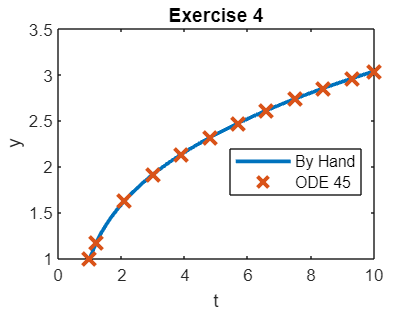

% Maximum ERROR: 0.0017118 
% Add a label to the axis and a legend
xlabel('t');
ylabel("y");

Your solution should show the definition of the inline function, the computation of its solution in this interval, the computation of the exact solution at the computed grid points, the computation of the maximum error, and a plot of the exact and approximate solutions.

%Your axes should be appropriately labeled and include a legend.

## Exercise 5

Objective: Solve and visualize an ODE that cannot be solved by hand with `ode45`.

Details: Solve the IVP

`y' = 1 - t y / 2, y(0) = -1`

from `t=0` to `t=10`

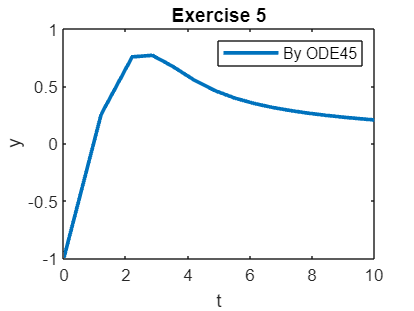

f = @(t,y) 1-t*y/2;
% The initial conditions
t0 = 0;
y0 = -1;
t1 = 10;
sol45 = ode45(f, [t0, t1], y0);
plot(sol45.x, sol45.y, 'LineWidth', 2);
xlabel("t")
ylabel("y")
title("Exercise 5")
legend("By ODE45")

Your solution should show you defining the inline function, computing the solution in this interval, and plotting it.

Your axes should be appropriately labeled

## Exercise 6 - When things go wrong

Objective: Solve an ode and explain the warning message

Details: Solve the IVP:

`y' = y^3 - t^2, y(0) = 1`

from `t=0` to `t=1`.

f = @(t,y) y.^3 -t.^2;
t0 = 0;
y0 = 1;
t1 = 1;
so_l45 = ode45(f, [t0, t1], y0);
disp(so_l45);

     solver: 'ode45'
    extdata: [1×1 struct]
          x: [0 0.1000 0.2000 0.3000 0.4000 0.4359 0.4719 0.4778 0.4837 0.4925 0.5013 0.5021 0.5028 0.5043 0.5055 0.5058 0.5061 0.5062 0.5064 0.5064 0.5065 0.5065 0.5066 0.5066 0.5066 0.5066 0.5066 0.5066 0.5066 0.5066 0.5066 0.5066 … ] (1×79 double)
          y: [1 1.1177 1.2876 1.5664 2.1736 2.6658 3.7974 4.1684 4.6754 5.9556 9.7040 10.4841 11.4887 14.8548 21.3359 24.6598 30.2592 36.3816 48.8621 55.5370 65.9974 80.9988 115.2764 126.6970 142.3615 181.1455 293.5338 316.9315 346.9954 … ] (1×79 double)
      stats: [1×1 struct]
      idata: [1×1 struct]



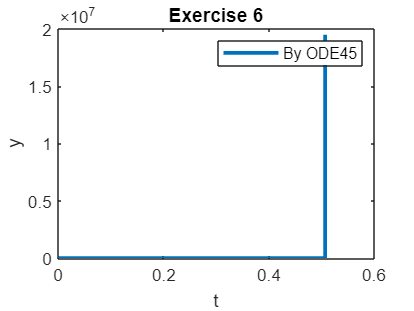

plot(so_l45.x, so_l45.y, 'LineWidth', 2);
xlabel("t")
ylabel("y")
title("Exercise 6")
legend("By ODE45")

% when it goes a little bit above 0.5, it goes up to 
% ~10.^7
% The reason why this generates error message: 
% is because the from looking at iode, I can see that discontinuity at
% time t = 0.5 The solution of the curve becomes really stiff around that
% time will small step size. Therefore, this can't integrate properly. The
% reason why this became this can be "x^3" rate of change is too stiff. 

Your solution should show you defining the inline function, and computing the solution in this interval.

If you try to plot the solution, you should find that the solution does not make it all the way to t = 1.

In the comments explain why MATLAB generates the warning message that you may see, or fails to integrate all the way to t=1. HINT: Try plotting the direction field for this with IODE.

## Using symbolic variables to define functions

We can define symbolic variables to let MATLAB know that these variables will be used for exact computations

% Start by defining the variables as symbolic
syms t s x y

% Define a function by simply writing its expression

f = cos(t)

$$f = \cos\left(t\right)$$

g = sin(t)

$$g = \sin\left(t\right)$$

h = exp(2*x)

$$h = {\mathrm{e}}^{2\,x}$$


% We can manipulate these functions

simplify(f^2+g^2)

$$ans = 1$$

diff(h)

$$ans = 2\,{\mathrm{e}}^{2\,x}$$


% We can plot a function defined symbolically using the command |ezplot|.
% Learn about the command |ezplot|:

help ezplot

 ezplot   (NOT RECOMMENDED) Easy to use function plotter
 
  ezplot is not recommended. Use FPLOT or FIMPLICIT instead.
 
    ezplot(FUN) plots the function FUN(X) over the default domain
    -2*PI < X < 2*PI, where FUN(X) is an explicitly defined function of X.
 
    ezplot(FUN2) plots the implicitly defined function FUN2(X,Y) = 0 over
    the default domain -2*PI < X < 2*PI and -2*PI < Y < 2*PI.
 
    ezplot(FUN,[A,B]) plots FUN(X) over A < X < B.
    ezplot(FUN2,[A,B]) plots FUN2(X,Y) = 0 over A < X < B and A < Y < B.
 
    ezplot(FUN2,[XMIN,XMAX,YMIN,YMAX]) plots FUN2(X,Y) = 0 over
    XMIN < X < XMAX and YMIN < Y < YMAX.
 
    ezplot(FUNX,FUNY) plots the parametrically defined planar curve FUNX(T)
    and FUNY(T) over the defau

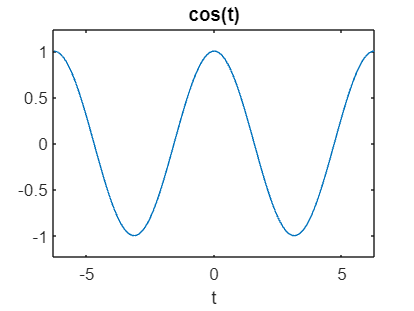


% Plot the function |f(t)| and |h(x)|

ezplot(f)

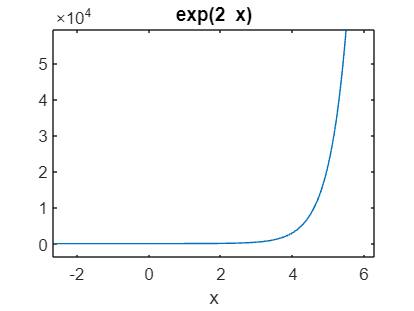

ezplot(h)

If we try to evaluate the function `f(0)`, we get an error message.

The symbolic variables are not meant to be used to evaluate functions, but to manipulate functions, compute derivatives, etc. To evaluate a function using symbolic variables is a little cumbersome:

% We need to substitute the variable by a value:

subs(f,t,pi)

$$ans = -1$$

This expression means: In the expression `f`, substitute the variable `t` by the number `pi`.

% If we use a value where the cosine does not have a "nice" expression, we
% need to approximate the result:

subs(f,t,2)

$$ans = \cos\left(2\right)$$


% We need to use the command |eval|

eval(subs(f,t,2))

ans = -0.4161

## Exercise 7

Objective: Define a function using symbolic variables and manipulate it.

Details: Define the function `f(x) = sin(x)cos(x)`

Use MATLAB commands to obtain a simpler form of this function, compute value of this function for `x=pi/4` and `x=1`, and plot its graph.

% Start by defining the variables as symbolic
syms hi f x

% Define a function by simply writing its expression

f = sin(x)*cos(x)

$$f = \cos\left(x\right)\,\sin\left(x\right)$$

% We can manipulate these functions

hi = simplify(f)

$$hi = \frac{\sin\left(2\,x\right)}{2}$$


% Evaulate value at pi/4
subs(hi, x, pi/4)

$$ans = \frac{1}{2}$$

% sym(1/2)
% Evaulate value at 1
eval(subs(hi, x, 1))

ans = 0.4546

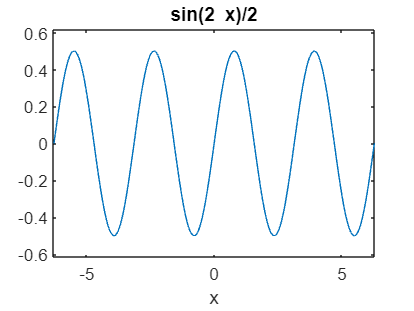

% ans = 0.4546

ezplot(hi)

## Obtaining Picard approximations

Consider an initial value problem

`y' = 1 + y` `y(0) = 0`

First we need to define the variables we will be using

syms t s y;

% We then need to define the function f

hi = 1+y; % we define it without the @(t,y) because it is a symbolic function

% We set up our initial approximation phi_0 = 0:

phi=[sym(0)];   % we will keep a list with all the approximations
phi

$$phi = 0$$


% Set up a loop to get successive approximations using Picard iterations

N=5;

for i = 1:N
    func=subs(hi,y,phi(i));    % prepare function to integrate: y -> previous phi
    func=subs(func,t,s);      % variable of integration is s, so we need to change
    % t -> s
    
    newphi = int(func, s, 0 ,t);   % integrate to find next approximation
    
    phi=cat(2,phi,[newphi]);       % update the list of approximations by adding new phi
end

% Show the last approximation

phi(N+1)

$$ans = \frac{t\,\left(t^{4}+5\,t^{3}+20\,t^{2}+60\,t+120\right)}{120}$$

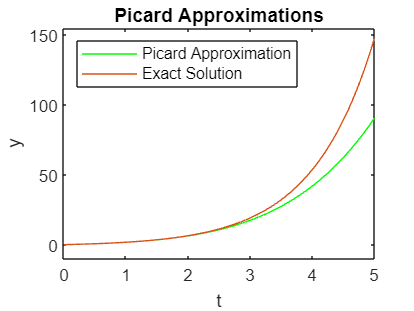


% Plot the approximation just found

picard=ezplot(phi(N+1),[0,5]);
set(picard,'Color','green');         % set the color of the graph to green

% In this case, the exact solution is
%
% |y=e^t-1|
%
% Compare the approximation and the exact solutions

hold on;
exact=ezplot(exp(t)-1,[0,5]);

xlabel('t');
ylabel('y');
title('Picard Approximations');
legend('Picard Approximation', 'Exact Solution','Location','NorthWest');

## Exercise 8

clear;
clf;
syms t s y;

lol = 1+y.^2; 

% We set up our initial approximation phi_hi = 1:
phi_hi = sym(1)

$$phi\_hi = 1$$

% In terms of efficiency, don't store old phis 

% Set up a loop to get successive approximations using Picard iterations
N=5; % To get phi_hi_5

for i = 1:N
    func=subs(lol,y,phi_hi);   
    func=subs(func,t,s);     
    phi_hi = 1 + int(func, s, 0 ,t);   % integrate to find next approximation
end

% Show the last approximation

phi_hi

$$phi\_hi = \frac{65536\,t^{31}}{109876902975}+\frac{32768\,t^{30}}{3544416225}+\frac{33636352\,t^{29}}{445414972275}+\frac{2189312\,t^{28}}{5119712325}+\frac{3771621376\,t^{27}}{2017062172125}+\frac{3496164352\,t^{26}}{522942044625}+\frac{1852466944\,t^{25}}{91423434375}+\frac{28632512\,t^{24}}{536350815}+\frac{234841821952\,t^{23}}{1884677169375}+\frac{14839805056\,t^{22}}{56729413125}+\frac{1241511104\,t^{21}}{2483105625}+\frac{400722032\,t^{20}}{456080625}+\frac{1157035136\,t^{19}}{808782975}+\frac{4159073344\,t^{18}}{1915538625}+\frac{1240970116\,t^{17}}{402026625}+\frac{175768612\,t^{16}}{42567525}+\frac{1111144976\,t^{15}}{212837625}+\frac{29636504\,t^{14}}{4729725}+\frac{4842328\,t^{13}}{675675}+\frac{1221016\,t^{12}}{155925}+\frac{425608\,t^{11}}{51975}+\frac{1108\,t^{10}}{135}+\frac{22376\,t^{9}}{2835}+\frac{764\,t^{8}}{105}+\frac{32\,t^{7}}{5}+\frac{16\,t^{6}}{3}+\frac{64\,t^{5}}{15}+\frac{10\,t^{4}}{3}+\frac{8\,t^{3}}{3}+2\,t^{2}+2\,t+1$$

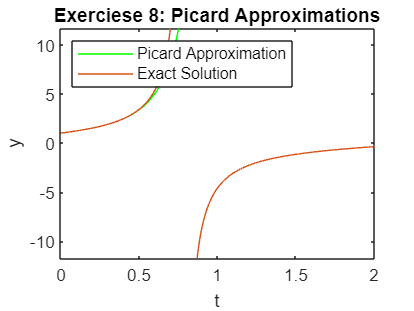

% Plot the approximation just found

picard=ezplot(phi_hi,[0,2]);
set(picard,'Color','green');         % set the color of the graph to green

hold on;
exact=ezplot(tan(pi/4 + t),[0,2]);
hold off;
xlabel('t');
ylabel('y');
title('Exerciese 8: Picard Approximations');
legend('Picard Approximation', 'Exact Solution','Location','NorthWest');

Find the Picard approximation phi_5. For better efficiency, do not keep all the previous approximations.

Compute the exact solution (by hand), and plot both on the same figure for comparison, as above.

Label your axes and include a legend.

HINT. The initial condition has 1 instead of 0, so the Picard method needs to be adapted.